## **Importing Dataset and Network**

dataset_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Dataset\hpl\hpl_final\hpl_final_jpg\');
imds = imageDatastore(dataset_path, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
network_path = fullfile('G:\MEngg Materials\Sem 3\ENGN 8535 Data Analytics\Project\Data-analytics\net.mat');
net = load(network_path);

## **Feature maps display**

layer = 7;
name = net.net.Layers(layer).Name;
channels = 1:16;
I = deepDreamImage(net.net,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         1.55 |               1 |
|           2 |         1.53 |               1 |
|           3 |         1.51 |               1 |
|           4 |         1.49 |               1 |
|           5 |         1.47 |               1 |
|           6 |         1.45 |               1 |
|           7 |         1.43 |               1 |
|           8 |         1.41 |               1 |
|           9 |         1.38 |               1 |
|          10 |         1.36 |               1 |
|==============================================|


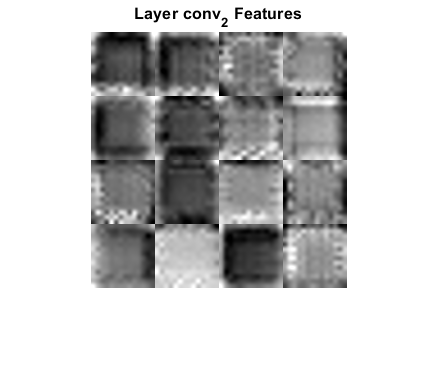

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

layer = 17;
name = net.net.Layers(layer).Name;
channels = 1:64;
I = deepDreamImage(net.net,layer,channels,'PyramidLevels',1);

|==============================================|
|  Iteration  |  Activation  |  Pyramid Level  |
|             |   Strength   |                 |
|==============================================|
|           1 |         0.35 |               1 |
|           2 |         0.23 |               1 |
|           3 |         0.12 |               1 |
|           4 |         0.02 |               1 |
|           5 |         0.08 |               1 |
|           6 |         0.18 |               1 |
|           7 |         0.27 |               1 |
|           8 |         0.36 |               1 |
|           9 |         0.45 |               1 |
|          10 |         0.53 |               1 |
|==============================================|


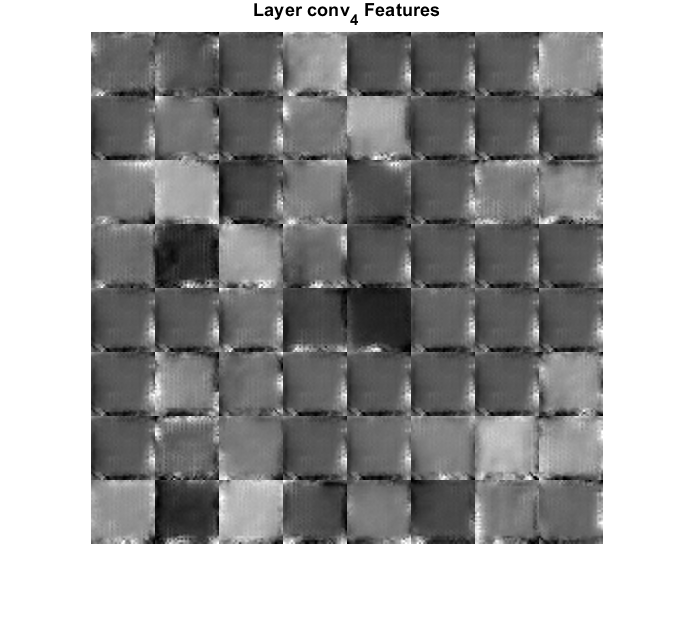

figure
I = imtile(I,'ThumbnailSize',[64 64]);
imshow(I)
title(['Layer ',name,' Features']);

[imdsTrain,imdsTest,imdsVal] = splitEachLabel(imds,0.7, 0.15, 0.15,'randomized');

## **Classification of Test data**

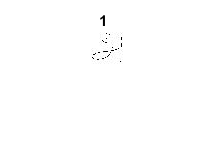

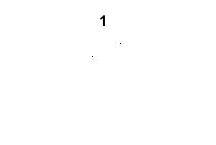

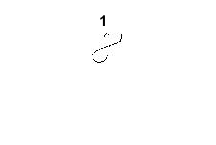

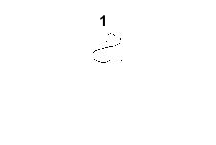

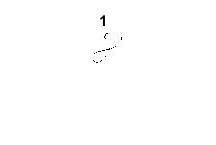

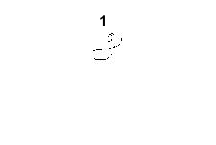

test_results = char(classify(net.net,imdsTest));
count = 0;
TestLabels = char(imdsTest.Labels);
for i = 1:length(test_results)
    comp = strcmp(TestLabels(i,:), test_results(i,:));
    if (comp == 1)
        count = count + 1;
        if (i<10)
            figure;
            H = imshow(imread(imdsVal.Files{i}));
            title(TestLabels(i,:))
        end
    end
end

test_accuracy = count/length(test_results)

test_accuracy = 0.6661